Exercise#1

clc;
clear;
close all;

format compact;

% Nominal system values
R = 25e3;
C = 10e-6;

% 1. Create transfer function
T = tf(1, [R*C 1]);

% 2. Calculate time constant
Tc = R*C;

% 3. Calculate rise time (10% to 90%)
Tr = log(9)*Tc;

% 4. Calculate settling time (2% criterion)
Ts = -log(0.02)*Tc;

% 5. Calculate resistor for settling time of 0.1 seconds
R2 = 0.1/(-log(0.02)*C);

% 6. Create new transfer function
T2 = tf(1, [R2*C 1]);

% Display results
disp('Original transfer function T(s):');

Original transfer function T(s):


T


T =
 
      1
  ----------
  0.25 s + 1
 
Continuous-time transfer function.



disp('Time constant Tc:');

Time constant Tc:


Tc

Tc = 0.2500


disp('Rise time Tr:');

Rise time Tr:


Tr

Tr = 0.5493


disp('Settling time Ts:');

Settling time Ts:


Ts

Ts = 0.9780


disp('New resistor R2:');

New resistor R2:


R2

R2 = 2.5562e+03


disp('New transfer function T2(s):');

New transfer function T2(s):


T2


T2 =
 
        1
  -------------
  0.02556 s + 1
 
Continuous-time transfer function.



% Plot response to 10 V step input
figure;
step(10*T);
hold on;
step(10*T2);
grid on;
title('Response to 10 V Step Input');
xlabel('Time (seconds)');
ylabel('Output Voltage (V)');
legend('Original T(s)', 'New T2(s)');
hold off;


exercise#2

clc;
clear;
close all;

% Question 1
R1 = 10e3;
C1 = 100e-6;
tau1 = R1*C1;
G1 = tf(1, [tau1 1]);

% Question 2
R2 = 4.7e3;
C2 = 220e-6;
tau2 = R2*C2;
G2 = tf(1, [tau2 1]);

% Question 3
K3 = 2.5;
tau3 = 8/4;
G3 = tf(K3, [tau3 1]);

% Display results
disp('Question 1');

Question 1


G1


G1 =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.


tau1

tau1 = 1

dcgain(G1)

ans = 1

pole(G1)

ans = -1

stepinfo(G1)

ans = struct with fields:
         RiseTime: 2.1970
    TransientTime: 3.9121
     SettlingTime: 3.9121
      SettlingMin: 0.9045
      SettlingMax: 0.9993
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9993
         PeakTime: 7.3222


disp('Question 2');

Question 2


G2


G2 =
 
       1
  -----------
  1.034 s + 1
 
Continuous-time transfer function.


tau2

tau2 = 1.0340

dcgain(G2)

ans = 1

pole(G2)

ans = -0.9671

stepinfo(G2)

ans = struct with fields:
         RiseTime: 2.2717
    TransientTime: 4.0451
     SettlingTime: 4.0451
      SettlingMin: 0.9045
      SettlingMax: 0.9993
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9993
         PeakTime: 7.5712


disp('Question 3');

Question 3


G3


G3 =
 
    2.5
  -------
  2 s + 1
 
Continuous-time transfer function.


tau3

tau3 = 2

dcgain(G3)

ans = 2.5000

pole(G3)

ans = -0.5000

stepinfo(G3)

ans = struct with fields:
         RiseTime: 4.3940
    TransientTime: 7.8241
     SettlingTime: 7.8241
      SettlingMin: 2.2613
      SettlingMax: 2.4983
        Overshoot: 0
       Undershoot: 0
             Peak: 2.4983
         PeakTime: 14.6444

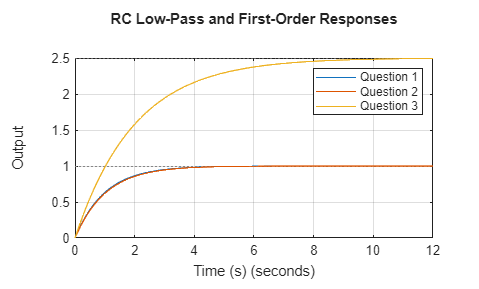


% Plot responses
figure;
step(G1, G2, G3);
grid on;
legend('Question 1', 'Question 2', 'Question 3');
title('RC Low-Pass and First-Order Responses');
xlabel('Time (s)');
ylabel('Output');

exercise#3

clc;
clear;
close all;

% Required specifications
K = 2.5;
Ts = 8;

% Calculate time constant
tau = Ts/4;

% Create transfer function
G = tf(K, [tau 1]);

% Display results
disp('Transfer Function:');

Transfer Function:


G


G =
 
    2.5
  -------
  2 s + 1
 
Continuous-time transfer function.



disp('Time Constant:');

Time Constant:


tau

tau = 2


disp('System Pole:');

System Pole:


pole(G)

ans = -0.5000


disp('DC Gain / Final Value:');

DC Gain / Final Value:


dcgain(G)

ans = 2.5000


disp('Step Response Information:');

Step Response Information:


stepinfo(G)

ans = struct with fields:
         RiseTime: 4.3940
    TransientTime: 7.8241
     SettlingTime: 7.8241
      SettlingMin: 2.2613
      SettlingMax: 2.4983
        Overshoot: 0
       Undershoot: 0
             Peak: 2.4983
         PeakTime: 14.6444

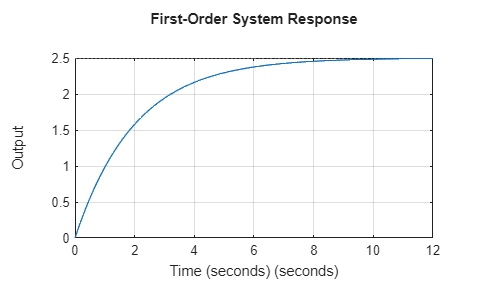


% Plot unit-step response
figure;
step(G);
grid on;
title('First-Order System Response');
xlabel('Time (seconds)');
ylabel('Output');

experiment #1

%task#1 %%%%%%



clc;
clear;
close all;

K = 2;
tau = 5;

G = tf(K, [tau 1]);

figure;
step(G);
grid on;

title('Unit-Step Response: G(s) = 2/(5s + 1)');
xlabel('Time (s)');
ylabel('Output y(t)');

system_pole = pole(G)

system_pole = -0.2000

steady_state_gain = dcgain(G)

steady_state_gain = 2

response_info = stepinfo(G)

response_info = struct with fields:
         RiseTime: 10.9850
    TransientTime: 19.5604
     SettlingTime: 19.5604
      SettlingMin: 1.8090
      SettlingMax: 1.9987
        Overshoot: 0
       Undershoot: 0
             Peak: 1.9987
         PeakTime: 36.6111

Experiment#2

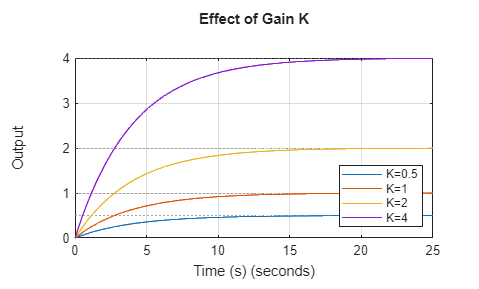

clc;
clear;
close all;

tau = 4;
K_values = [0.5 1 2 4];

figure;
hold on;

for K = K_values
    G = tf(K, [tau 1]);
    step(G);
end

grid on;
legend('K=0.5', 'K=1', 'K=2', 'K=4', ...
       'Location', 'southeast');

title('Effect of Gain K');
xlabel('Time (s)');
ylabel('Output');

hold off;

experiment#3

% Lab Exercise 1: RC Circuit
clc;
clear;
close all;

format compact;

% Nominal system values
R = 25e3;
C = 10e-6;

% 1) Create the transfer function
T = tf(1, [R*C 1]);

% 2) Calculate the time constant
Tc = R*C;

% 3) Calculate the rise time (10% to 90%)
Tr = 2.2*Tc;

% 4) Calculate the 2% settling time
Ts = 4*Tc;

% 5) Calculate new resistor for Ts = 0.1 seconds
R2 = 0.1/(4*C);

% 6) Create the new transfer function
T2 = tf(1, [R2*C 1]);

% Display results
disp('Original transfer function:');

Original transfer function:


T


T =
 
      1
  ----------
  0.25 s + 1
 
Continuous-time transfer function.



disp('Time constant Tc (seconds):');

Time constant Tc (seconds):


Tc

Tc = 0.2500


disp('Rise time Tr (seconds):');

Rise time Tr (seconds):


Tr

Tr = 0.5500


disp('Settling time Ts (seconds):');

Settling time Ts (seconds):


Ts

Ts = 1


disp('New resistor R2 (ohms):');

New resistor R2 (ohms):


R2

R2 = 2500


disp('New transfer function T2:');

New transfer function T2:


T2


T2 =
 
       1
  -----------
  0.025 s + 1
 
Continuous-time transfer function.


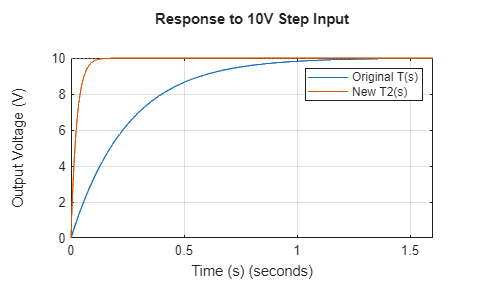


% Compare responses to a 10V step input
figure;
step(10*T);
hold on;
step(10*T2);
grid on;
title('Response to 10V Step Input');
legend('Original T(s)', 'New T2(s)');
xlabel('Time (s)');
ylabel('Output Voltage (V)');
hold off;

verification of exp#1 and exp#2

clc;
clear;
close all;

% Question 1
R1 = 10e3;
C1 = 100e-6;
tau1 = R1*C1;
G1 = tf(1, [tau1 1]);

% Question 2
R2 = 4.7e3;
C2 = 220e-6;
tau2 = R2*C2;
G2 = tf(1, [tau2 1]);

% Question 3
K3 = 2.5;
tau3 = 8/4;
G3 = tf(K3, [tau3 1]);

% Display transfer functions and results
disp('Question 1:');

Question 1:


G1


G1 =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.


tau1

tau1 = 1

dcgain(G1)

ans = 1

stepinfo(G1)

ans = struct with fields:
         RiseTime: 2.1970
    TransientTime: 3.9121
     SettlingTime: 3.9121
      SettlingMin: 0.9045
      SettlingMax: 0.9993
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9993
         PeakTime: 7.3222


disp('Question 2:');

Question 2:


G2


G2 =
 
       1
  -----------
  1.034 s + 1
 
Continuous-time transfer function.


tau2

tau2 = 1.0340

dcgain(G2)

ans = 1

stepinfo(G2)

ans = struct with fields:
         RiseTime: 2.2717
    TransientTime: 4.0451
     SettlingTime: 4.0451
      SettlingMin: 0.9045
      SettlingMax: 0.9993
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9993
         PeakTime: 7.5712


disp('Question 3:');

Question 3:


G3


G3 =
 
    2.5
  -------
  2 s + 1
 
Continuous-time transfer function.


pole(G3)

ans = -0.5000

dcgain(G3)

ans = 2.5000

stepinfo(G3)

ans = struct with fields:
         RiseTime: 4.3940
    TransientTime: 7.8241
     SettlingTime: 7.8241
      SettlingMin: 2.2613
      SettlingMax: 2.4983
        Overshoot: 0
       Undershoot: 0
             Peak: 2.4983
         PeakTime: 14.6444

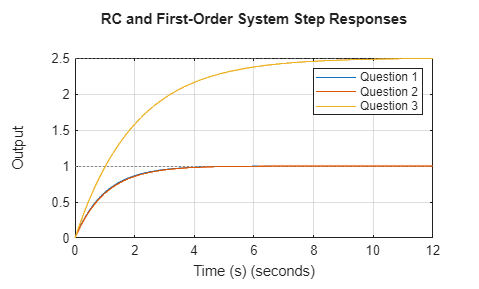


% Plot all three step responses
figure;
step(G1, G2, G3);
grid on;
legend('Question 1', 'Question 2', 'Question 3');
title('RC and First-Order System Step Responses');
xlabel('Time (s)');
ylabel('Output');